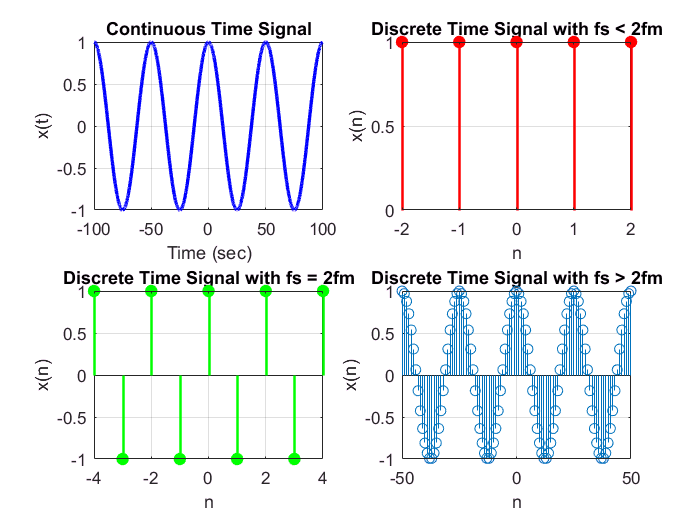

% Step 1: Generate and plot the continuous time signal
t = -100:0.01:100;  
fm = 0.02;          
x = cos(2 * pi * fm * t);  
subplot(2, 2, 1); 
plot(t, x, 'b', 'LineWidth', 2);  
xlabel('Time (sec)'); ylabel('x(t)');
title('Continuous Time Signal'); 
grid on;

% Step 2: Plot discrete time signal with fs < 2fm
fs1 = 0.02;  
n1 = -2:2;   
x1 = cos(2 * pi * fm * n1 / fs1);  
subplot(2, 2, 2);
stem(n1, x1, 'r', 'filled', 'LineWidth', 1.5); 
title('Discrete Time Signal with fs < 2fm');
xlabel('n'); ylabel('x(n)'); 
grid on;

% Step 3: Plot discrete time signal with fs = 2fm
fs2 = 0.04;  
n2 = -4:4;   
x2 = cos(2 * pi * fm * n2 / fs2);  
subplot(2, 2, 3);
stem(n2, x2, 'g', 'filled', 'LineWidth', 1.5); 
title('Discrete Time Signal with fs = 2fm');
xlabel('n'); ylabel('x(n)'); 
grid on;

% Step 4: Plot discrete time signal with fs > 2fm
fs3 = 0.5;   
n3 = -50:50; 
x3 = cos(2 * pi * fm * n3 / fs3);  
subplot(2, 2, 4); 
stem(n3, x3); 
title('Discrete Time Signal with fs > 2fm');
xlabel('n'); ylabel('x(n)');
grid on;